clc
clear
load("data\Kalman_Data_Stille.mat")
u_in(:,12001:end)=[];
y_meas(:,1501:end)=[];
t = linspace(0,30,12000);
t2 = linspace(0,30,1500);

mean(u_in(1:3,:).')

ans =     0.2287   -0.0084    9.6679


var(u_in(1:3,:).')

ans = 1.0e-04 *

    0.6132    0.6425    0.8811


mean(u_in(4:6,:).')

ans =    -0.0066   -0.0045   -0.0060


var(u_in(4:6,:).')

ans = 1.0e-05 *

    0.0885    0.1038    0.0757


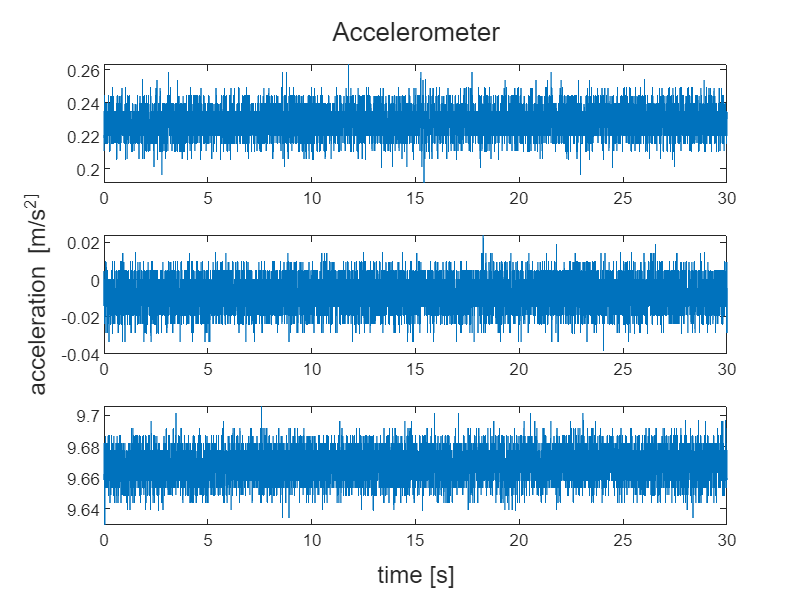


figure()
f = tiledlayout('vertical');
nexttile
plot(t,u_in(1,:).')
nexttile
plot(t,u_in(2,:).')
nexttile
plot(t,u_in(3,:).')
xlabel(f,"time [s]")
ylabel(f,"acceleration [m/s^2]")
sgtitle(strcat("Accelerometer"))
saveas(gcf,strcat("Images/Accelerometer"),'epsc')

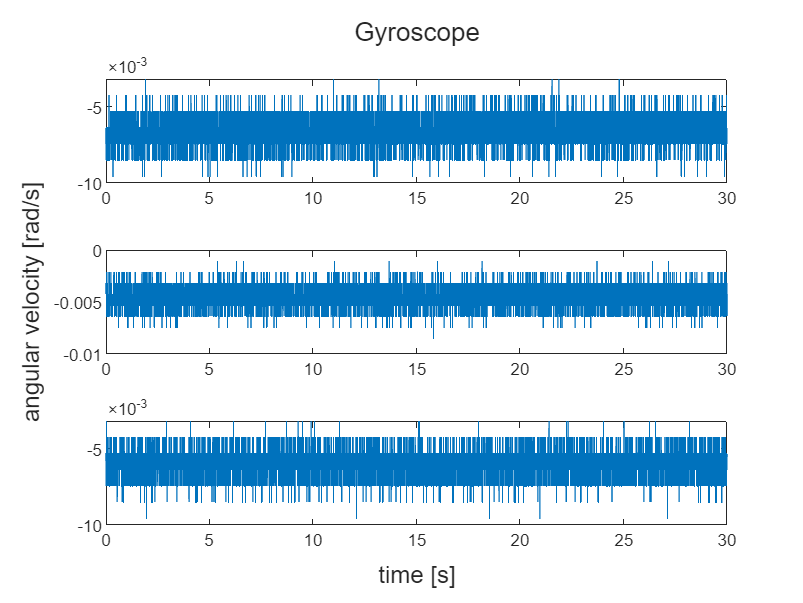


figure()
f = tiledlayout('vertical');
nexttile
plot(t,u_in(4,:).')
nexttile
plot(t,u_in(5,:).')
nexttile
plot(t,u_in(6,:).')
xlabel(f,"time [s]")
ylabel(f,"angular velocity [rad/s]")
sgtitle(strcat("Gyroscope"))
saveas(gcf,strcat("Images/Gyroscope"),'epsc')

mean(y_meas(1:3,:).')

ans =  -212.4020    6.3337 -509.5326


var(y_meas(1:3,:).')

ans =    13.5260    3.0646    5.6309


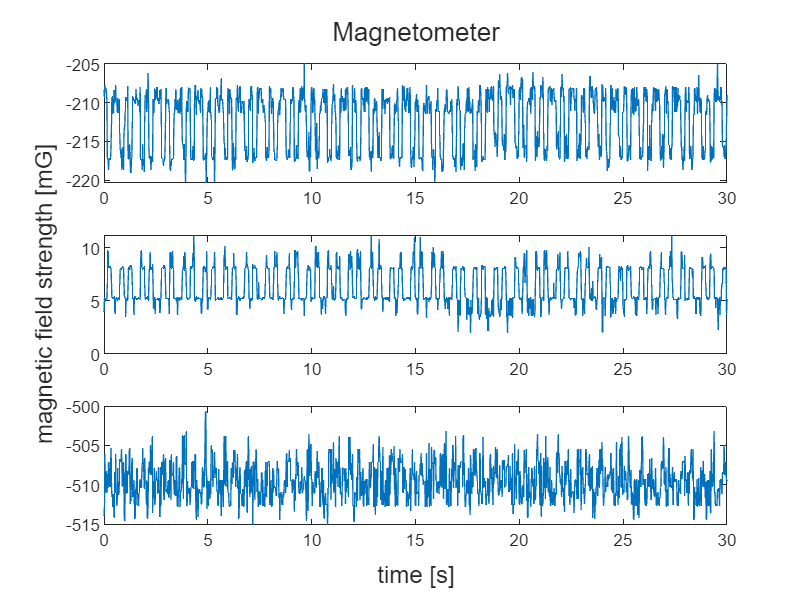

figure()
f = tiledlayout('vertical');
nexttile
plot(t2,y_meas(1,:).')
nexttile
plot(t2,y_meas(2,:).')
nexttile
plot(t2,y_meas(3,:).')
title(f,"Magnetometer")
xlabel(f,"time [s]")
ylabel(f,"magnetic field strength [mG]")
saveas(gcf,strcat("Images/Magnetometer"),'epsc')

data = y_meas(4,:);
mean(y_meas(4,:).')

ans = 0.4311

var(y_meas(4,:).')

ans = 0.0840

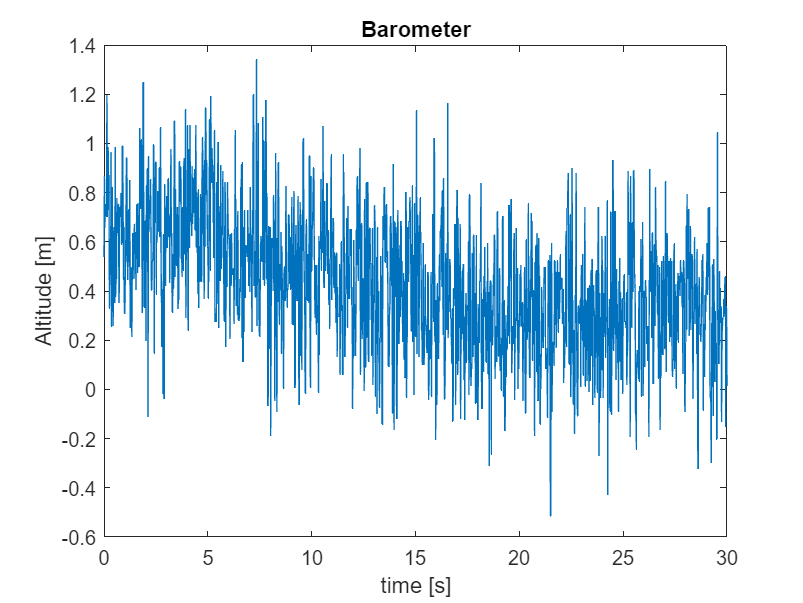

figure()
plot(t2, y_meas(4,:))
title("Barometer")
xlabel("time [s]")
ylabel("Altitude [m]")
saveas(gcf,strcat("Images/Barometer"),'epsc')

mean(y_meas(5:7,:).')

ans =    -0.0109    0.0143    0.1747


var(y_meas(5:7,:).')

ans = 1.0e-08 *

    0.0834    0.0385    0.1988


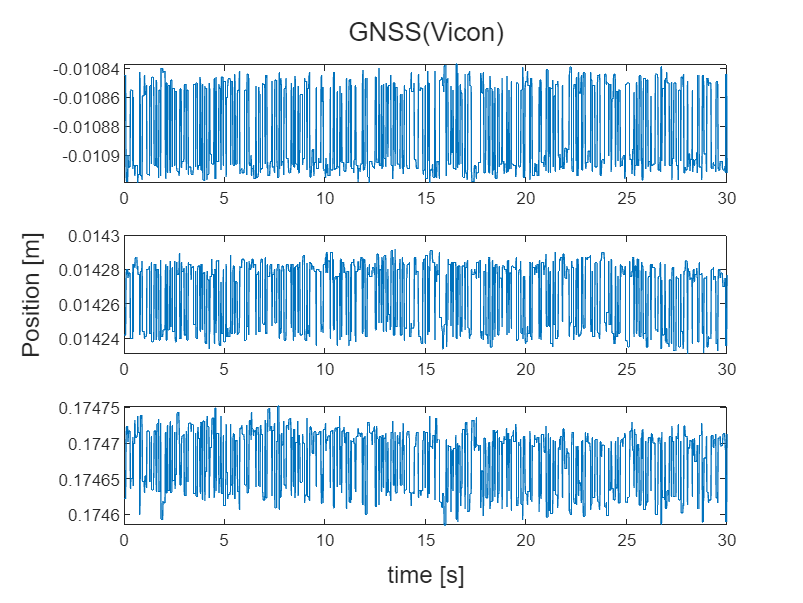

figure()
f = tiledlayout('vertical');
nexttile
plot(t2,y_meas(5,:).')
nexttile
plot(t2,y_meas(6,:).')
nexttile
plot(t2,y_meas(7,:).')
title(f,"GNSS(Vicon)")
xlabel(f,"time [s]")
ylabel(f,"Position [m]")
saveas(gcf,strcat("Images/GNSS_Vicon"),'epsc')